# Newton's Law of Cooling 

Instructions are in the task pane to the left. Complete and submit each task one at a time.

## Task 1

Solve the ODE and plot the solution.

*Remember to define your ODE function at the bottom of this script.*

The temperature of a pie cooling to room temperature after being taken out of an oven is given by

*d**T/d**t*=*c*(*T*−23)  where *c*=−0.028.

When the pie is removed from the oven (*t*=0 minutes), the pie's temperature is 175°*C*. 

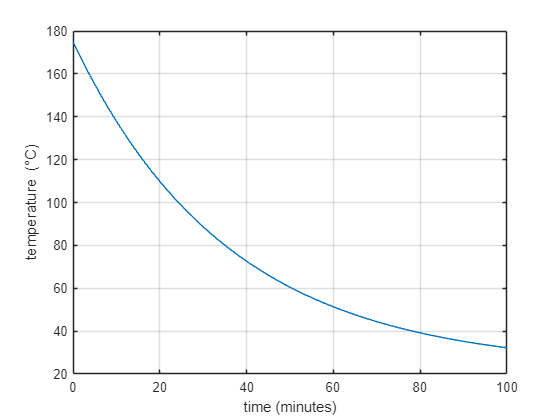

tRange = [0 100];
T0 = 175;
[tSol, TSol] = ode45(@pieODEfun, tRange, T0);
plot(tSol, TSol)
grid on

% Label axes
xlabel("time (minutes)")
ylabel("temperature (\circC)")

## Task 1 (continued)

Define the ODE function for   where  -0.028.

function dTdt = pieODEfun(t, T)
    c = -0.028;
    dTdt = c*(T-23);
end